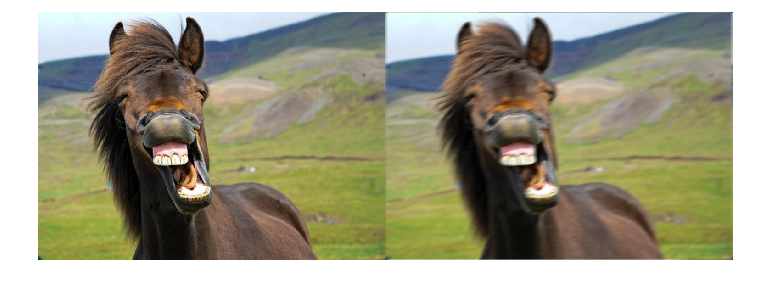

% Read the image
image = imread('horse.jpg');

% Define the strength of the blur (adjust as needed)
blur_strength = 10;

% Apply the directional blur
blurred_image = applyDirectionalBlur(image, blur_strength);

% Display the original and blurred images
montage({image, blurred_image});

function blurred_image = applyDirectionalBlur(image, blur_strength)
    % Convert the image to double
    image = im2double(image);
    
    % Get the size of the image
    [rows, cols, ~] = size(image);
    
    % Generate a random angle between 0 and 360 degrees
    angle = rand * 360;
    
    % Create a directional filter
    h = fspecial('motion', blur_strength, angle);
    
    % Apply the filter to the image
    blurred_image = imfilter(image, h, 'conv', 'circular');
end
